% visualize expression on MST
% Author: Chang Lu
% c.lu@maastrichtuniversity.nl

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

% datapath = [currentFolder,filesep,'data',filesep,'mix with cd163'];
% or set you own path( replace the sentence above to the example below):
datapath = '/Users/changlu/DATA/OLIVIA/30 clusters CDK5 New'; % your own data path

addpath(genpath('fun'));
directory = [datapath,filesep,'results',filesep];
if ~exist(directory,'dir')
    mkdir(directory);
end

files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


## Load data

%check the mat files in the datapath
load([datapath,filesep, 'cosine_kmedoids_k=30']); % add your own mat files
load([datapath,filesep, 'cellmarker_rescale_intergration_t=3']);

## visualization of ki67+

ki67pic = 'A_ki67 PE594';
run('script/overlayki67andnuclei');

plaquesname = fileNames;
uni_cluster = unique(labels);
ki=[];
for i= 1:length(plaquesname)
    load([nuancefolder,filesep,plaquesname{i},filesep,'poski67.mat']);
    ki=[ki;poski67(selected_idx{i})];
end
p=zeros(1,length(uni_cluster));
for i = 1:length(uni_cluster)
    p(i) = sum(ki(labels==uni_cluster(i)))/sum(labels==uni_cluster(i));
end


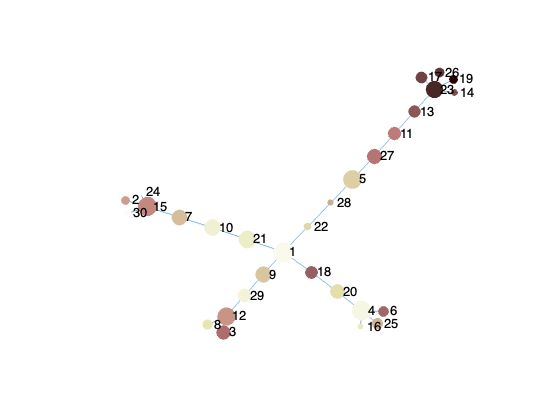

% c = categorical(1:length(uni_cluster));
% figure; bar(c,p);
% xlswrite([directory,'ki67-70.xlsx'],[1:length(uni_cluster);p]);
% 
fig = draw_mst_expr(labels, centers,'cosine',p);
saveas(fig,[directory,'ki67+.jpg'])

## visualization:  expression of biomarkers on MST

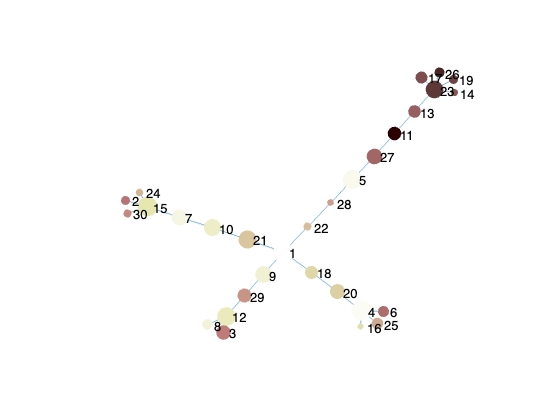

bio_name = 'A_Perilipin2 AF488';
p = centers(:, strcmp(bio_name, biomarkername));
fig = draw_mst_expr(labels, centers,'cosine',p);
figname = 'Perilipin2';
saveas(fig,[directory,figname,'.jpg'])